# chapter 10: signal detection theory

figure
hold on
x = 0:0.1:10;
% firing rate of a neuron in the absence of a visual stimulus
y = normpdf(x, 5, 1.5)

y =     0.0010    0.0013    0.0016    0.0020    0.0024    0.0030    0.0036    0.0044    0.0053    0.0063    0.0076    0.0091    0.0107    0.0127    0.0149    0.0175    0.0204    0.0236    0.0273    0.0314    0.0360    0.0410    0.0466    0.0526    0.0592    0.0663    0.0739    0.0821    0.0907    0.0998    0.1093    0.1192    0.1295    0.1399    0.1506    0.1613    0.1721    0.1827    0.1931    0.2033    0.2130    0.2221    0.2307    0.2385    0.2455    0.2516    0.2567    0.2607    0.2636    0.2654


plot(x,y)
% firing rate of a neuron in response to a visual stimulus
z = normpdf(x, 6, 1.5)

z =     0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0013    0.0016    0.0020    0.0024    0.0030    0.0036    0.0044    0.0053    0.0063    0.0076    0.0091    0.0107    0.0127    0.0149    0.0175    0.0204    0.0236    0.0273    0.0314    0.0360    0.0410    0.0466    0.0526    0.0592    0.0663    0.0739    0.0821    0.0907    0.0998    0.1093    0.1192    0.1295    0.1399    0.1506    0.1613    0.1721    0.1827    0.1931    0.2033


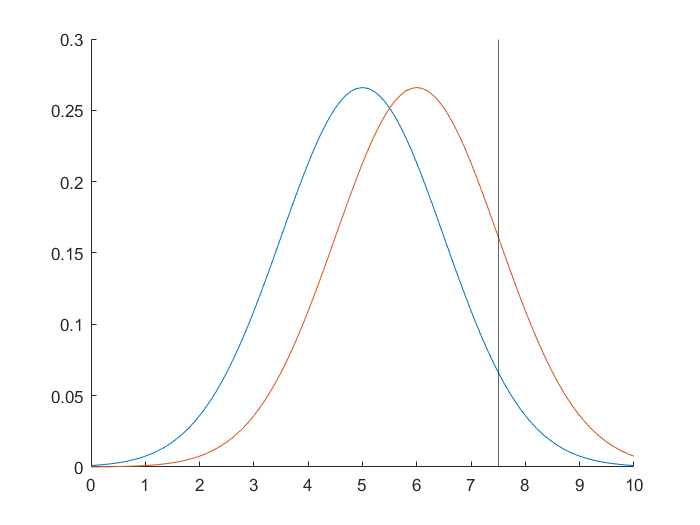

plot(x,z)
% criterion level: 7.5 = mu + sigma
% 1, firing rate > 7.5 (stimulus present)
% 0, firing rate < 7.5 (no stimulus)
xline(7.5)

## reciever operating characteristic (ROC)

$\text{TPR} =\frac{\text{TP}}{\text{P}} =  \frac{\text{TP}}{\text{TP}+ \text{FN}}$ (precision rate, sensitivity, or recall)

$\text{FPR} =\frac{\text{FP}}{\text{N}} =  \frac{\text{FP}}{\text{FP}+ \text{TN}}$ (fall-out)

$\text{TNR} =\frac{\text{TN}}{\text{N}}= \frac{\text{TN}}{\text{TN}+\text{FP}}$ (specifity)

$\text{FNR} =\frac{\text{FN}}{\text{T}}= \frac{\text{TN}}{\text{FN}+\text{TP}}$ (miss rate)

ROC curve: plot **FPR** against **TPR**

figure
FPR = 1 - cumsum(y)/10

FPR =     0.9999    0.9998    0.9996    0.9994    0.9992    0.9989    0.9985    0.9981    0.9976    0.9969    0.9962    0.9953    0.9942    0.9929    0.9914    0.9897    0.9876    0.9853    0.9825    0.9794    0.9758    0.9717    0.9670    0.9618    0.9558    0.9492    0.9418    0.9336    0.9245    0.9146    0.9036    0.8917    0.8788    0.8648    0.8497    0.8336    0.8164    0.7981    0.7788    0.7585    0.7372    0.7149    0.6919    0.6680    0.6435    0.6183    0.5926    0.5666    0.5402    0.5137


TPR = 1 - cumsum(z)/10

TPR =     1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9991    0.9988    0.9985    0.9982    0.9977    0.9972    0.9966    0.9958    0.9949    0.9938    0.9926    0.9911    0.9893    0.9873    0.9849    0.9822    0.9790    0.9754    0.9713    0.9667    0.9614    0.9555    0.9489    0.9415    0.9333    0.9242    0.9142    0.9033    0.8913    0.8784    0.8644    0.8493    0.8332    0.8160    0.7977    0.7784    0.7581


plot(FPR, TPR)
hold on
random_guess = 0:0.1:1

random_guess =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


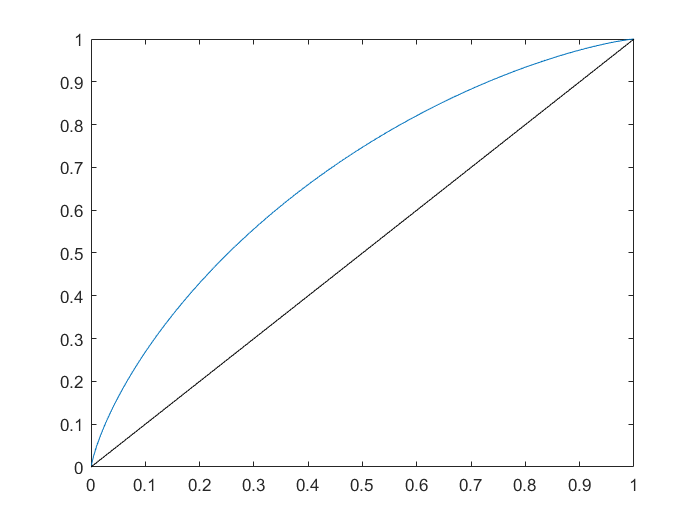

plot(random_guess, random_guess, 'Color','k')